# Anal3 9. gyakorlat. Variációszámítás 2.

File: segedszamitasok_2017_11_15_gyak9.mlx

Author: Peter Polcz (ppolcz@gmail.com) 

Created on 2017. November 15.

persist = pcz_persist;

│   - Persistence - empty initialized (file independent) [run ID: 48, 074]Persistence - empty 2017.11.15. Wednesday, 15:48:09 [run ID: 


## Dido feladvány különböző kezdeti értékek mellett

syms x y real

fcn = x^2 + (y+sqrt(3))^2 == 4

$$fcn = {\left(y+\sqrt{3}\right)}^{2}+x^{2}=4$$

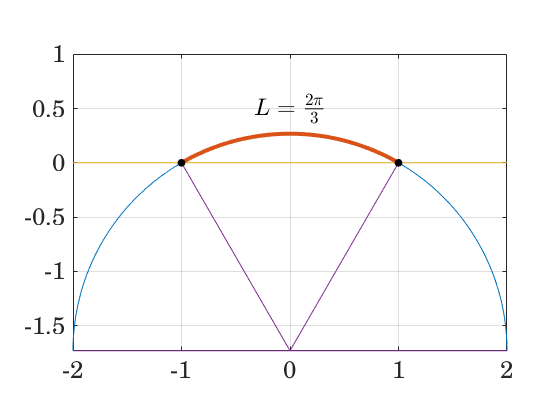

s3 = sqrt(3);
figure
fimplicit(fcn,[-2, 2, -s3 1]), hold on, grid on, axis equal
fimplicit(fcn,[-2, 2, 0 1],'LineWidth',3), hold on, grid on, axis equal
fplot(sym(0), [-2,2])
plot([2 0 1 0 -1 0 -2],[-s3 -s3 0 -s3 0 -s3 -s3])
plot([-1 1],[0,0],'.k','MarkerSize',20)
set(gca,persist.font.axis18{:})
text(0,0.5,'$L = \frac{2\pi}{3}$', persist.font.latex18c{:})
print -dpng -r300 /home/ppolcz/Repositories/Bitbucket/control-systems/users/public_html/files/targyak/anal3/szorgalmi/fig/dido.png

## Láncgörbe

syms a b lambda C x real 
syms y(x)

fcn = 1/sqrt((x+lambda)^2 - C^2)

$$fcn = \frac{1}{\sqrt{{\left(\lambda +x\right)}^{2}-C^{2}}}$$

int(fcn), diff(acosh(x+lambda))

$$ans = \log\left(\lambda +x+\sqrt{{\left(\lambda +x\right)}^{2}-C^{2}}\right)$$

$$ans = \frac{1}{\sqrt{\lambda +x-1}\,\sqrt{\lambda +x+1}}$$

rewrite(acosh(x/C),'log')

$$ans = \log\left(\frac{x}{C}+\sqrt{\frac{x}{C}-1}\,\sqrt{\frac{x}{C}+1}\right)$$

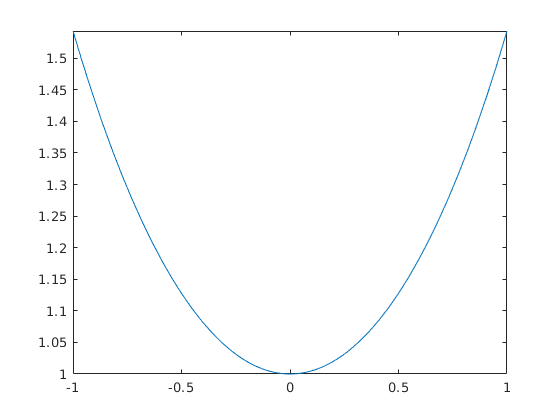

figure,
fplot(cosh(x), [-1,1])

KIF = rewrite(cosh(x),'exp') == rewrite(cosh(log(sym(2))),'exp')

$$KIF = \frac{{\mathrm{e}}^{-x}}{2}+\frac{{\mathrm{e}}^{x}}{2}=\frac{5}{4}$$

KIF = rewrite(cosh(x),'exp') == rewrite(cosh(sym(1)),'exp')

$$KIF = \frac{{\mathrm{e}}^{-x}}{2}+\frac{{\mathrm{e}}^{x}}{2}=\frac{{\mathrm{e}}^{-1}}{2}+\frac{\mathrm{e}}{2}$$

diff(acosh(x))

$$ans = \frac{1}{\sqrt{x-1}\,\sqrt{x+1}}$$